addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

human_dist = load('Humans/AreaDistances.mat');
human_size = load('allhumandata.mat');human_size = human_size.humandata;

monks=load('Monks/alldata.mat');
monks_dist=load('Monks/intermediate_files');

% Human Data
disp(human_dist.area_labels)

  Columns 1 through 13

    {'V1all'}    {'V1v'}    {'V1d'}    {'V2v'}    {'V2d'}    {'V3v'}    {'V3d'}    {'V3A'}    {'V3B'}    {'LO1'}    {'LO2'}    {'TO1'}    {'TO2'}

  Columns 14 through 25

    {'hV4'}    {'VO1'}    {'VO2'}    {'PHC1'}    {'PHC2'}    {'IPS0'}    {'IPS1'}    {'IPS2'}    {'IPS3'}    {'IPS4'}    {'IPS5'}    {'SPL1'}

  Columns 26 through 27

    {'FEF'}    {'IFS'}



dist_to_data_idx = [2,3,4,5,6,7,14,15,16,17,18,8,9,10,11,12,13,19,20,21,22,23,24,25];
from_v1_idx = find(human_dist.alluniqueroinodepairs(:,1)==0);
distance_from_v1_rh = human_dist.allareadistancesavglayer_rh(from_v1_idx,:);
distance_from_v1_lh = human_dist.allareadistancesavglayer_lh(from_v1_idx,:);
dist_from_v1_rh = distance_from_v1_rh(dist_to_data_idx-1,:);
dist_from_v1_lh = distance_from_v1_lh(dist_to_data_idx-1,:);
human_labels_vd = human_dist.area_labels(dist_to_data_idx);

meanhumans_cortdist_rh = mean(dist_from_v1_rh,2,'omitnan');
meanhumans_cortdist_lh = mean(dist_from_v1_lh,2,'omitnan');

meanhumans_cortdist_rh1234=[];
meanhumans_cortdist_rh1234(1)=0;
meanhumans_cortdist_rh1234(2)=[meanhumans_cortdist_rh(3)+meanhumans_cortdist_rh(4)]/2;
meanhumans_cortdist_rh1234(3)=[meanhumans_cortdist_rh(5)+meanhumans_cortdist_rh(6)]/2;
meanhumans_cortdist_rh1234=[meanhumans_cortdist_rh1234,meanhumans_cortdist_rh(7:end)'];

meanhumans_cortdist_lh1234=[];
meanhumans_cortdist_lh1234(1)=0;
meanhumans_cortdist_lh1234(2)=[meanhumans_cortdist_lh(3)+meanhumans_cortdist_lh(4)]/2;
meanhumans_cortdist_lh1234(3)=[meanhumans_cortdist_lh(5)+meanhumans_cortdist_lh(6)]/2;
meanhumans_cortdist_lh1234=[meanhumans_cortdist_lh1234,meanhumans_cortdist_lh(7:end)'];

meanhumans_cortdist1234=[meanhumans_cortdist_lh1234+meanhumans_cortdist_lh1234]/2;

% Human Labels
human_labels =           [{'V1', 'V2', 'V3'},human_labels_vd{7:end}];
disp(human_labels)

  Columns 1 through 13

    {'V1'}    {'V2'}    {'V3'}    {'hV4'}    {'VO1'}    {'VO2'}    {'PHC1'}    {'PHC2'}    {'V3A'}    {'V3B'}    {'LO1'}    {'LO2'}    {'TO1'}

  Columns 14 through 21

    {'TO2'}    {'IPS0'}    {'IPS1'}    {'IPS2'}    {'IPS3'}    {'IPS4'}    {'IPS5'}    {'SPL1'}



human_areadistfromV1 =   [ 0, 1, 2, 3, 4, 5, 6, 7, 3, 3, 3, 4, 5, 6, 4, 5, 6, 7, 8, 9, 7];
human_fellemanhierarchy = [1, 2, 3, 5, 6, 6, 7, 7, 4, 4, 5, 5, 5, 5, 5, 5, 6, 6, 6, 6, 6]-1;

% Human Analysis from Separate Data
% calculate sum of retinal (removing v7), parietal, and frontal areas
for i = 1:2
    surfacearea_smoothwm{i} = [human_size.retino_surfacearea_smoothwm{i}([1:13,15:18],:);human_size.parietal_surfacearea_smoothwm{i}];
    surfacearea_pial{i} = [human_size.retino_surfacearea_pial{i}([1:13,15:18],:);human_size.parietal_surfacearea_pial{i}];
end

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
human_surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

human_bothhemi_SA = [human_surfacearea_avg{1} + human_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(human_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(human_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(human_bothhemi_SA(5:6,:),1);

SA_sumvd_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;human_bothhemi_SA(7:end,:)];

human_bothhemi_SA = [human_surfacearea_avg{1} human_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(human_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(human_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(human_bothhemi_SA(5:6,:),1);

SA_catvd_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;human_bothhemi_SA(7:end,:)];

neo_size = load('Humans/NeonatalComparison/allvisualareadata.mat');
neo_dist = load('Humans/AreaDistances_neonate.mat');

surfacearea_smoothwm{1} = neo_size.allsubjs_smoothwm_rh([2:14,16:end],:);surfacearea_smoothwm{2} = neo_size.allsubjs_smoothwm_lh([2:14,16:end],:);
surfacearea_pial{1} = neo_size.allsubjs_pial_rh([2:14,16:end],:);surfacearea_pial{2} = neo_size.allsubjs_pial_lh([2:14,16:end],:);

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
neo_surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

neo_bothhemi_SA = [neo_surfacearea_avg{1} + neo_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(neo_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(neo_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(neo_bothhemi_SA(5:6,:),1);

SA_sumvd_neo = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;neo_bothhemi_SA(7:end,:)];

neo_bothhemi_SA = [neo_surfacearea_avg{1} neo_surfacearea_avg{2}];

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = sum(neo_bothhemi_SA(1:2,:),1);
V2_sumhemis_sumvd = sum(neo_bothhemi_SA(3:4,:),1);
V3_sumhemis_sumvd = sum(neo_bothhemi_SA(5:6,:),1);

SA_catvd_neo = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;neo_bothhemi_SA(7:end,:)];

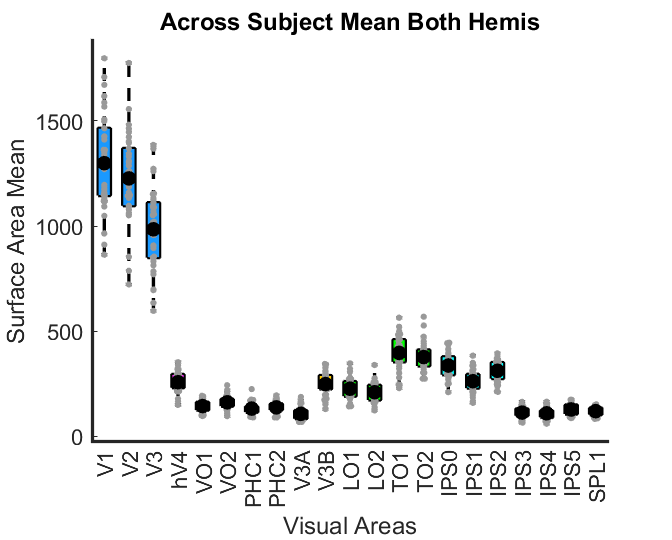

%% Plot distributions of area sizes

allvisual_numbers=[1,2,3,4,5,6,150,151,152,153,154,50,51,52,100,101,102,103];
allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','hV4','VO1','VO2','PHC1','PHC2','V3A','V3B','LO1','LO2','TO1','TO2'};
allparietal_numbers=1:7; %201-207
allparietal_labels={'IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1'};

EVCrois_human=1:6; EVCcolor=[0.1 0.6 1];
V4rois_human=7; V4color=[1 0.2 1];
ventralrois_human=8:11; ventralcolor=[1 0.2 0.2];
dorsalrois_human=12:13; dorsalcolor=[1 .8 0];
lateralrois_human=15:18; lateralcolor=[0 1 0];
parietalrois_human=19:25; parietalcolor=[0 1 1];

% concatenate all human area ROIs, labels, and colors
allrois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human};
alllabels_human=[allvisual_labels, allparietal_labels];
use_colorscale_human_all=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,2,1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1)];

alllabs = cat(2,{'V1','V2','V3'},alllabels_human(7:end));

use_colorscale_inv_all=flipud(use_colorscale_human_all);
figure
hold on
h=boxplot(SA_sumvd_neo','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(use_colorscale_inv_all(j,:)),'FaceAlpha',1);
end
hold on
plotSpread(SA_sumvd_neo','distributionColors',use_colorscale_human_all(4:end,:)*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(SA_sumvd_neo'),'k.','MarkerSize',30);
xlim([0.5 size(SA_sumvd_neo,1)+.5])
yticks(0:500:2000)
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabs)],'xticklabel', alllabs);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

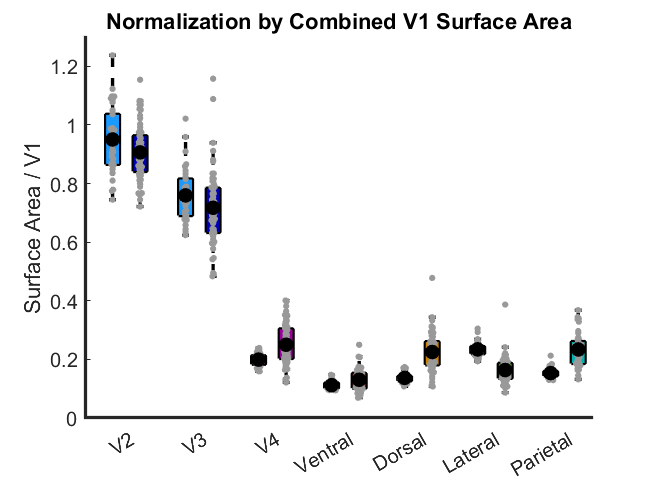

addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

neo_all = SA_sumvd_neo;
human_all = SA_sumvd_human;

evccolor=[0.1 0.6 1];
v4color=[1 0.2 1];
ventralcolor=[1 0.2 0.2];
dorsalcolor=[1 .8 0];
parietalcolor=[0 1 1];
lateralcolor=[0 1 0];
use_colorscale_neo=[evccolor;evccolor;v4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
use_colorscale_inv_neo = flipud(use_colorscale_neo);

evccolor=[0 0 0.7];
v4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0];
lateralcolor=[0.2784    0.5216    0.1451];
parietalcolor=[0 0.7 0.7];
use_colorscale_adult=[evccolor;evccolor;v4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
use_colorscale_inv_adult = flipud(use_colorscale_adult);

human_dorsal_idx =  [1, 2, 3, 9, 10, 15:21];
human_lateral_idx = [1, 2, 3, 11:14];
human_ventral_idx = [1, 2, 3, 4:8];

v2_idx = 2;
v3_idx = 3;
v4_idx = 4;
dorsal_idx = human_dorsal_idx(4:5);
parietal_idx = human_dorsal_idx(6:end);
lateral_idx = human_lateral_idx(4:end);
ventral_idx = human_ventral_idx(5:end);
human_area_idx = {v2_idx,v3_idx,v4_idx,ventral_idx,dorsal_idx,lateral_idx,parietal_idx};

alllabels_combined = {'V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};

human_over_v1 = human_all./human_all(1,:);
neo_over_v1 = neo_all./neo_all(1,:);

normv1_combined_human = [];
normv1_combined_neo = [];
for i = 1:length(human_area_idx)
    normv1_combined_human = [normv1_combined_human;mean(human_over_v1(human_area_idx{i},:),1,'omitnan')];
    normv1_combined_neo = [normv1_combined_neo;mean(neo_over_v1(human_area_idx{i},:),1,'omitnan')];
end

addnanneo = padarray(normv1_combined_neo,[1 size(normv1_combined_human,2) - size(normv1_combined_neo,2)],nan,'post');

% pad array with nan to get the same size as humans
concat_data = [];
concat_colorscale = [];
for i = 1:size(normv1_combined_human,1)
    concat_data = [concat_data; addnanneo(i,:); normv1_combined_human(i,:)];
    concat_colorscale = [concat_colorscale;use_colorscale_inv_adult(i,:);use_colorscale_inv_neo(i,:)];
end

% set groupings by species and areas to use factorgap in boxplot
g1 = sort([1:7,1:7]);
g2 = repmat(1:2,[1,7]);

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
hold on
h1=boxplot(concat_data',[g1' g2'],'factorgap',5,'colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(concat_data,1)
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   patch(get(h1(j),'XData'),get(h1(j),'YData'),concat_colorscale(j,:),'FaceAlpha',1);
end

plotSpread(concat_data','xValues',fliplr(xd),'distributionColors',concat_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(fliplr(xd),nanmean(concat_data'),'k.','MarkerSize',30);

% take average of x values for each area to put xticklabel in the middle
xt = [];
for i = 1:length(xd)/2
    xt(i) = (xd(2*i-1) + xd(2*i))/2;
end

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
ax.FontSize = 15;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',fliplr(xt),'xticklabel', alllabels_combined,'fontsize',12);
% xlabel('Visual Areas');
ylabel('Surface Area / V1');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 1.3])

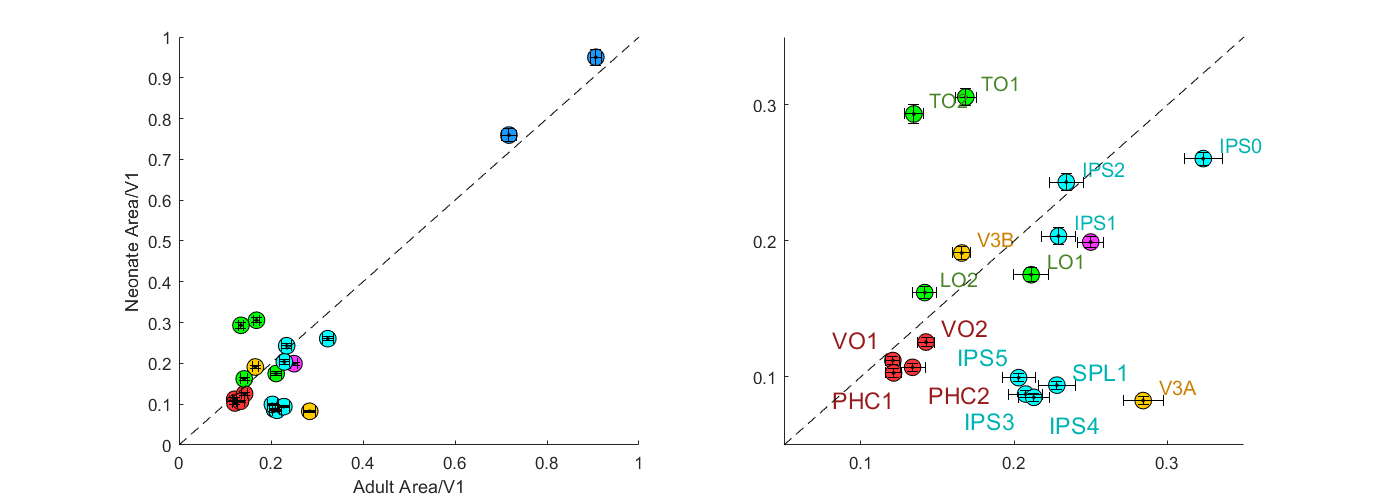

evc_idx = 2:3;
v4_idx = 4;
dorsal_idx = human_dorsal_idx(4:5);
parietal_idx = human_dorsal_idx(6:end);
lateral_idx = human_lateral_idx(4:end);
ventral_idx = human_ventral_idx(5:end);
human_area_idx = {evc_idx,v4_idx,ventral_idx,dorsal_idx,lateral_idx,parietal_idx};


evccolor=[0.1 0.6 1];
v4color=[1 0.2 1];
ventralcolor=[1 0.2 0.2];
dorsalcolor=[1 .8 0];
parietalcolor=[0 1 1];
lateralcolor=[0 1 0];
human_colors = [evccolor;v4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];

figure('Renderer', 'painters', 'Position', [10 10 1100 400]);
subplot(1,2,1);hold on;
for i = 1:length(human_area_idx)
    xval = mean(human_all(human_area_idx{i},:)./human_all(1,:),2,'omitnan');
    xstderr = std(human_all(human_area_idx{i},:)./human_all(1,:),[],2,'omitnan')./sqrt(size(human_all,2));
    yval = mean(neo_all(human_area_idx{i},:)./neo_all(1,:),2,'omitnan'); 
    ystderr = std(neo_all(human_area_idx{i},:)./neo_all(1,:),[],2,'omitnan')./sqrt(size(neo_all,2));
    plot(xval,yval,'ko','MarkerSize',10,'MarkerFaceColor',human_colors(i,:))
%     text(xval-0.01,yval,human_labels(human_area_idx{i}),'FontSize',8)
    errorbar(xval,yval,xstderr,'horizontal','k.')
    errorbar(xval,yval,ystderr,'vertical','k.')
end
plot([0 1],[0 1],'k--')
xlabel('Adult Area/V1')
ylabel('Neonate Area/V1')

offset=0.01;
distance_thresh = 0.03;

subplot(1,2,2);hold on;
for i = 2:length(human_area_idx)
    xval = mean(human_all(human_area_idx{i},:)./human_all(1,:),2,'omitnan');
    xstderr = std(human_all(human_area_idx{i},:)./human_all(1,:),[],2,'omitnan')./sqrt(size(human_all,2));
    yval = mean(neo_all(human_area_idx{i},:)./neo_all(1,:),2,'omitnan'); 
    ystderr = std(neo_all(human_area_idx{i},:)./neo_all(1,:),[],2,'omitnan')./sqrt(size(neo_all,2));
    
    plot(xval,yval,'ko','MarkerSize',10,'MarkerFaceColor',human_colors(i,:))
%     text(xval-0.01,yval,human_labels(human_area_idx{i}),'FontSize',8)
    errorbar(xval,yval,xstderr,'horizontal','k.')
    errorbar(xval,yval,ystderr,'vertical','k.')

    D = squareform(pdist([xval,yval]));
    dd = D<distance_thresh;
    dd(1:1+size(dd,1):end) = 0;
    adjust_labels = find(sum(dd,1)>0);
    keep_labels = find(sum(dd,1)==0);
    
    text(xval(keep_labels)+offset,yval(keep_labels)+offset,human_labels(human_area_idx{i}(keep_labels)),'FontSize',12,'color',use_colorscale_adult(i+1,:));
    
    mean_x = mean(xval(adjust_labels));
    mean_y = mean(yval(adjust_labels));
    
    find_quart_x = xval(adjust_labels)-mean_x;
    find_quart_y = yval(adjust_labels)-mean_y;
    
    for j = 1:length(adjust_labels)
        if find_quart_x(j)<0 && find_quart_y(j)<0
            text(xval(adjust_labels(j))-offset*4,yval(adjust_labels(j))-offset*2,human_labels(human_area_idx{i}(adjust_labels(j))),'FontSize',14,'color',use_colorscale_adult(i+1,:));
        elseif find_quart_x(j)>0 && find_quart_y(j)>0
            text(xval(adjust_labels(j))+offset,yval(adjust_labels(j))+offset,human_labels(human_area_idx{i}(adjust_labels(j))),'FontSize',14,'color',use_colorscale_adult(i+1,:));
        elseif find_quart_x(j)>0 && find_quart_y(j)<0
            text(xval(adjust_labels(j))+offset,yval(adjust_labels(j))-offset*2,human_labels(human_area_idx{i}(adjust_labels(j))),'FontSize',14,'color',use_colorscale_adult(i+1,:));
        elseif find_quart_x(j)<0 && find_quart_y(j)>0
            text(xval(adjust_labels(j))-offset*4,yval(adjust_labels(j))+offset*1.5,human_labels(human_area_idx{i}(adjust_labels(j))),'FontSize',14,'color',use_colorscale_adult(i+1,:));
        end
    end
end
plot([0 0.4],[0 0.4],'k--')
xlim([0.05 0.35])
ylim([0.05 0.35])
xticks(0:0.1:0.4)
yticks(0:0.1:0.4)

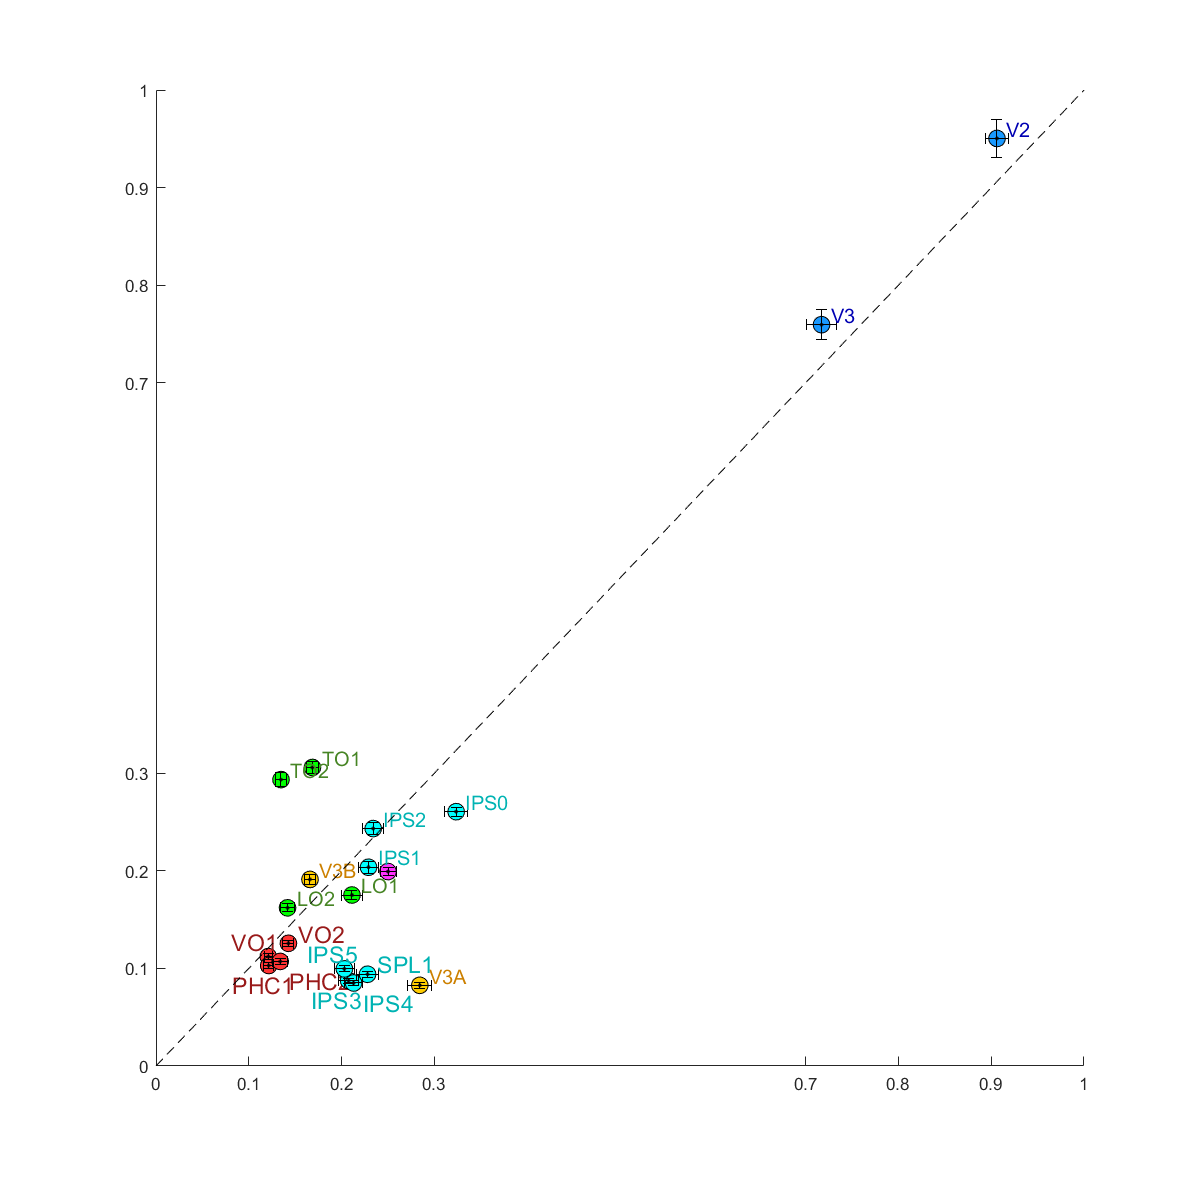

figure('Renderer', 'painters', 'Position', [10 10 1100 1100]);
hold on;

for i = 1:length(human_area_idx)
    xval = mean(human_all(human_area_idx{i},:)./human_all(1,:),2,'omitnan');
    xstderr = std(human_all(human_area_idx{i},:)./human_all(1,:),[],2,'omitnan')./sqrt(size(human_all,2));
    yval = mean(neo_all(human_area_idx{i},:)./neo_all(1,:),2,'omitnan'); 
    ystderr = std(neo_all(human_area_idx{i},:)./neo_all(1,:),[],2,'omitnan')./sqrt(size(neo_all,2));
    
    plot(xval,yval,'ko','MarkerSize',10,'MarkerFaceColor',human_colors(i,:))
%     text(xval-0.01,yval,human_labels(human_area_idx{i}),'FontSize',8)
    errorbar(xval,yval,xstderr,'horizontal','k.')
    errorbar(xval,yval,ystderr,'vertical','k.')

    D = squareform(pdist([xval,yval]));
    dd = D<distance_thresh;
    dd(1:1+size(dd,1):end) = 0;
    adjust_labels = find(sum(dd,1)>0);
    keep_labels = find(sum(dd,1)==0);
    
    text(xval(keep_labels)+offset,yval(keep_labels)+offset,human_labels(human_area_idx{i}(keep_labels)),'FontSize',12,'color',use_colorscale_adult(i+1,:));
    
    mean_x = mean(xval(adjust_labels));
    mean_y = mean(yval(adjust_labels));
    
    find_quart_x = xval(adjust_labels)-mean_x;
    find_quart_y = yval(adjust_labels)-mean_y;
    
    for j = 1:length(adjust_labels)
        if find_quart_x(j)<0 && find_quart_y(j)<0
            text(xval(adjust_labels(j))-offset*4,yval(adjust_labels(j))-offset*2,human_labels(human_area_idx{i}(adjust_labels(j))),'FontSize',14,'color',use_colorscale_adult(i+1,:));
        elseif find_quart_x(j)>0 && find_quart_y(j)>0
            text(xval(adjust_labels(j))+offset,yval(adjust_labels(j))+offset,human_labels(human_area_idx{i}(adjust_labels(j))),'FontSize',14,'color',use_colorscale_adult(i+1,:));
        elseif find_quart_x(j)>0 && find_quart_y(j)<0
            text(xval(adjust_labels(j))+offset,yval(adjust_labels(j))-offset*2,human_labels(human_area_idx{i}(adjust_labels(j))),'FontSize',14,'color',use_colorscale_adult(i+1,:));
        elseif find_quart_x(j)<0 && find_quart_y(j)>0
            text(xval(adjust_labels(j))-offset*4,yval(adjust_labels(j))+offset*1.5,human_labels(human_area_idx{i}(adjust_labels(j))),'FontSize',14,'color',use_colorscale_adult(i+1,:));
        end
    end
end
plot([0 1],[0 1],'k--')
xlim([0 1])
ylim([0 1])
xticks([0:0.1:0.3, 0.7:0.1:1])
yticks([0:0.1:0.3, 0.7:0.1:1])

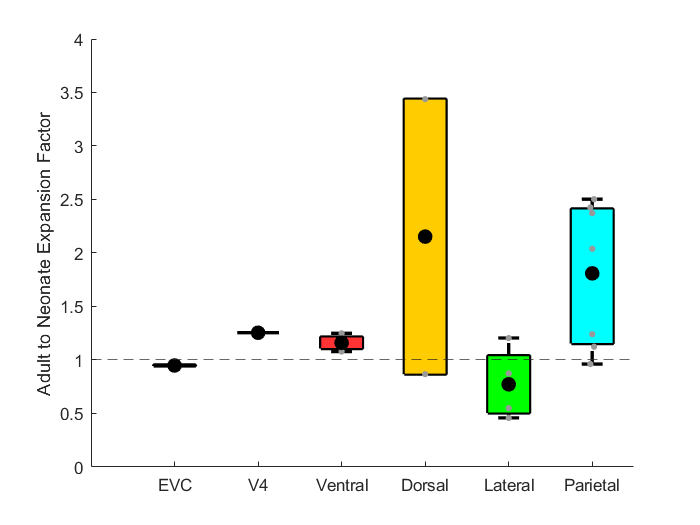

evc_idx = 2:3;
v4_idx = 4;
dorsal_idx = human_dorsal_idx(4:5);
parietal_idx = human_dorsal_idx(6:end);
lateral_idx = human_lateral_idx(4:end);
ventral_idx = human_ventral_idx(5:end);
human_area_idx = {evc_idx,v4_idx,ventral_idx,dorsal_idx,lateral_idx,parietal_idx};


use_colorscale_monkey=[evccolor;v4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor];
use_colorscale_inv_monkey = flipud(use_colorscale_monkey);

data_neo = mean(human_all(2:end,:)./human_all(1,:),2,'omitnan')./mean(neo_all(2:end,:)./neo_all(1,:),2,'omitnan');

groupingVar_neo = [1,1,2,3,3,3,3,4,4,5,5,5,5,6,6,6,6,6,6,6];
figure;hold on;
h1 = boxplot(data_neo,groupingVar_neo,'colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(human_colors,1)
   % have to extract x values from boxplot in order to set xlabels
   patch(get(h1(j),'XData'),get(h1(j),'YData'),use_colorscale_inv_monkey(j,:),'FaceAlpha',1);
end

for j=1:size(human_colors,1)
   % have to extract x values from boxplot in order to set xlabels
   plotSpread(mean(data_neo(human_area_idx{j}-1,:),2,'omitnan'),'xValues',j,'distributionColors',use_colorscale_inv_monkey(j,:)*0+[.6 .6 .6],'spreadWidth',.5)
   plot(j,mean(mean(data_neo(human_area_idx{j}-1,:),2,'omitnan')),'k.','MarkerSize',30);
end

ylabel('Adult to Neonate Expansion Factor')
xticks(1:6)
xticklabels(alllabels_combined)
yline(1,'--')
ylim([0 4])
box off;

surfacearea_adult_norm{1} = human_surfacearea_avg{1} ./ mean(human_surfacearea_avg{1},2,'omitnan');
surfacearea_adult_norm{2} = human_surfacearea_avg{2} ./ mean(human_surfacearea_avg{2},2,'omitnan');

surfacearea_neo_norm{1} = neo_surfacearea_avg{1} ./ mean(neo_surfacearea_avg{1},2,'omitnan');
surfacearea_neo_norm{2} = neo_surfacearea_avg{2} ./ mean(neo_surfacearea_avg{2},2,'omitnan');

adultvar = var(surfacearea_adult_norm{1}(:)-surfacearea_adult_norm{2}(:),'omitnan');
adultstd = std(surfacearea_adult_norm{1}(:)-surfacearea_adult_norm{2}(:),'omitnan');
neovar = var(surfacearea_neo_norm{1}(:)-surfacearea_neo_norm{2}(:),'omitnan');
neostd = std(surfacearea_neo_norm{1}(:)-surfacearea_neo_norm{2}(:),'omitnan');

data1 = human_surfacearea_avg{1}(:)-human_surfacearea_avg{2}(:);
data2 = neo_surfacearea_avg{1}(:)-neo_surfacearea_avg{2}(:);
include = ~isnan(data1);data1 = data1(include);
include = ~isnan(data2);data2 = data2(include);
[h,p] = vartest2(data1, data2);
disp([h, p])

    1.0000    0.0000



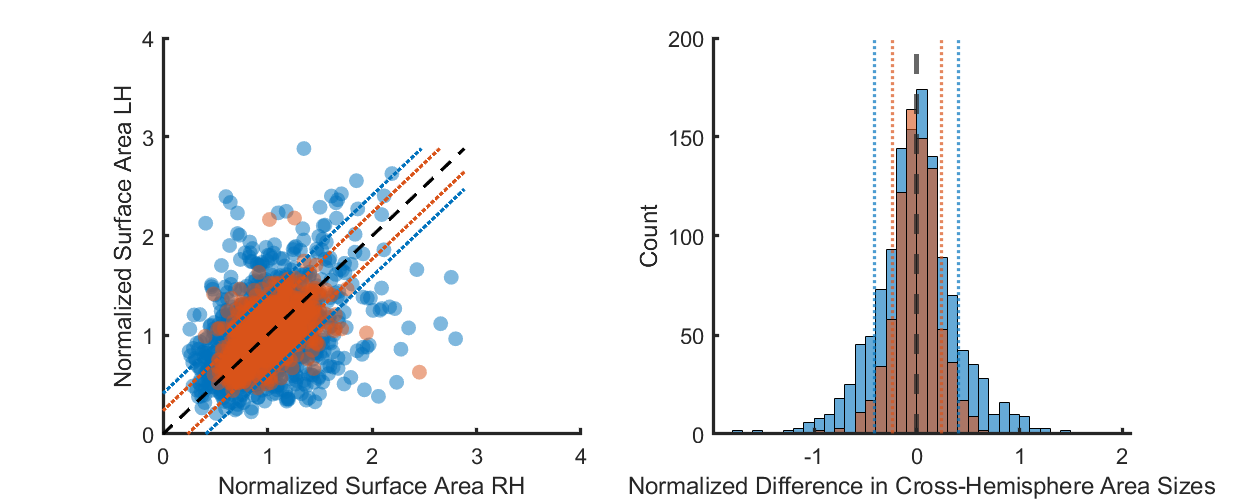



figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1)
s1 = scatter(surfacearea_adult_norm{1}(:),surfacearea_adult_norm{2}(:),80,'filled');
s1.MarkerFaceAlpha = 0.5;
hold on;
s2 = scatter(surfacearea_neo_norm{1}(:),surfacearea_neo_norm{2}(:),80,'filled');
s2.MarkerFaceAlpha = 0.5;
max_value=max([max(surfacearea_adult_norm{1}(:)),max(surfacearea_adult_norm{2}(:))]);
min_value=floor([min(surfacearea_adult_norm{1}(:)),min(surfacearea_adult_norm{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
plot([min_value, max_value-adultstd],[min_value+adultstd,max_value],':','Color',[0 0.4470 0.7410],'LineWidth',2)
plot([min_value+adultstd, max_value],[min_value,max_value-adultstd],':','Color',[0 0.4470 0.7410],'LineWidth',2)
plot([min_value, max_value-neostd],[min_value+neostd,max_value],':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot([min_value+neostd, max_value],[min_value,max_value-neostd],':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
xlabel('Normalized Surface Area RH')
ylabel('Normalized Surface Area LH')
% title(['Two Sample F Test: p = ',num2str(p)])
xlim([0 4])
ylim([0 4])
xticks(0:4)
yticks(0:4)
ax = gca;
ax.XAxis.LineWidth = 2;
ax.YAxis.LineWidth = 2;
ax.FontSize = 13;

subplot(1,2,2)
% figure('Renderer', 'painters', 'Position', [10 10 600 500]);
histogram((surfacearea_adult_norm{1}(:)-surfacearea_adult_norm{2}(:)));
hold on;
histogram((surfacearea_neo_norm{1}(:)-surfacearea_neo_norm{2}(:)));
xline(0,'--','linewidth',3)
xline(adultstd,':','Color',[0 0.4470 0.7410],'LineWidth',2)
xline(-adultstd,':','Color',[0 0.4470 0.7410],'LineWidth',2)
xline(neostd,':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
xline(-neostd,':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
box off
xlabel('Normalized Difference in Cross-Hemisphere Area Sizes')
ylabel('Count')
% legend('Humans','Monkeys')
% title(['Two Sample F Test: p = ',num2str(p)])
xticks(-2:2)
yticks(0:50:200)
ax = gca;
ax.XAxis.LineWidth = 2;
ax.YAxis.LineWidth = 2;
ax.FontSize = 13;

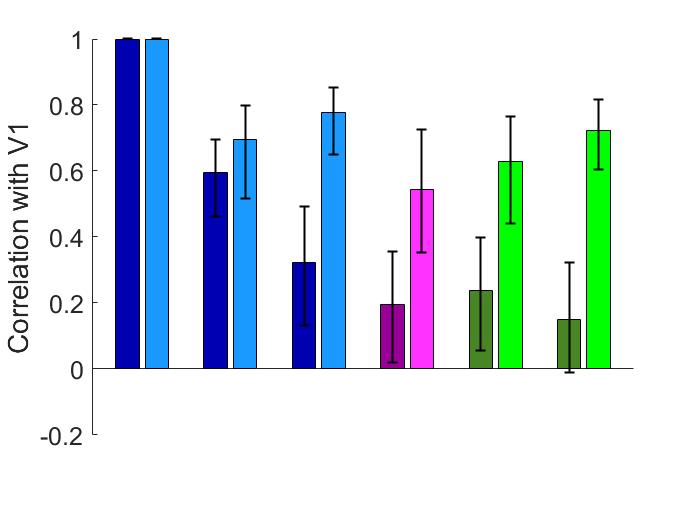

alllabels_human_merge = {'V1','V2','V3','V4','VO1','VO2','PHC1','PHC2','V3A','V3B','LO1','LO2','TO1','TO2','IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1'};

EVCcolor=[0 0 0.7];
V4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralcolor=[0.2784    0.5216    0.1451];
parietalcolor=[0 0.7 0.7];
frontalcolor=[.4 0 .4];
use_colorscale_human=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];%LGNcolor];

EVCcolor=[0.1 0.6 1];
V4color=[1 0.2 1];
ventralcolor=[1 0.2 0.2];
dorsalcolor=[1 .8 0];
lateralcolor=[0 1 0];
parietalcolor=[0 1 1];
use_colorscale_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];

% should probably do some bootstrapping here
all_area_corr_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
all_area_pval_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
stats_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge),2);
for i = 1:length(alllabels_human_merge)
    for j = 1:length(alllabels_human_merge)
        include = ~isnan(SA_catvd_human(i,:)) & ~isnan(SA_catvd_human(j,:));
        [r,p] = corr(SA_catvd_human(i,include)',SA_catvd_human(j,include)');
        temp = bootci(1000,@corr,[SA_catvd_human(i,include)',SA_catvd_human(j,include)']);
        stats_human(i,j,:) = temp(:,1,2);
        all_area_pval_human(i,j) = p;
        all_area_corr_human(i,j) = r;
    end
end

all_area_corr_neo = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
all_area_pval_neo = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
stats_neo = zeros(length(alllabels_human_merge),length(alllabels_human_merge),2);
for i = 1:length(alllabels_human_merge)
    for j = 1:length(alllabels_human_merge)
        include = ~isnan(SA_catvd_neo(i,:)) & ~isnan(SA_catvd_neo(j,:));
        [r,p] = corr(SA_catvd_neo(i,include)',SA_catvd_neo(j,include)');
        temp = bootci(1000,@corr,[SA_catvd_neo(i,include)',SA_catvd_neo(j,include)']);
        stats_neo(i,j,:) = temp(:,1,2);
        all_area_pval_neo(i,j) = p;
        all_area_corr_neo(i,j) = r;
    end
end

xlab = {'V1','V2','V3','V4','TO1/MT','TO2/MST'};
h_idx = [1:4,13,14];m_idx = [1:4,12,13];
hx = 1:3:3*6;mx = 2:3:3*6+1;
all_area_corr = [all_area_corr_human(h_idx,1), all_area_corr_neo(m_idx,1)];
h_color = [use_colorscale_human([1:4,7],:);use_colorscale_human(7,:)];
m_color = [use_colorscale_monkey([1:4,7],:);use_colorscale_monkey(7,:)];

figure;hold on;
for i = 1:length(h_idx)
    bar(hx(i),all_area_corr_human(h_idx(i),1),'FaceColor',h_color(i,:));
    errorbar(hx(i),all_area_corr_human(h_idx(i),1),all_area_corr_human(h_idx(i),1)-stats_human(h_idx(i),1,1),stats_human(h_idx(i),1,2)-all_area_corr_human(h_idx(i),1),'k','LineWidth',1.2)
end
for i = 1:length(m_idx)
    bar(mx(i),all_area_corr_neo(m_idx(i),1),'FaceColor',m_color(i,:));
    errorbar(mx(i),all_area_corr_neo(m_idx(i),1),all_area_corr_neo(m_idx(i),1)-stats_neo(m_idx(i),1,1),stats_neo(m_idx(i),1,2)-all_area_corr_neo(m_idx(i),1),'k','LineWidth',1.2)
end
xticks(1.5:3:3*7)
xticklabels(xlab)
ax = gca;
% ax.XAxis.TickLength = [0 0];
% set(gca,'xtick',[])
ax.XAxis.Visible = 'off';
ax.FontSize = 15;
ylabel('Correlation with V1')
% legend('Human','Monkey')
box off

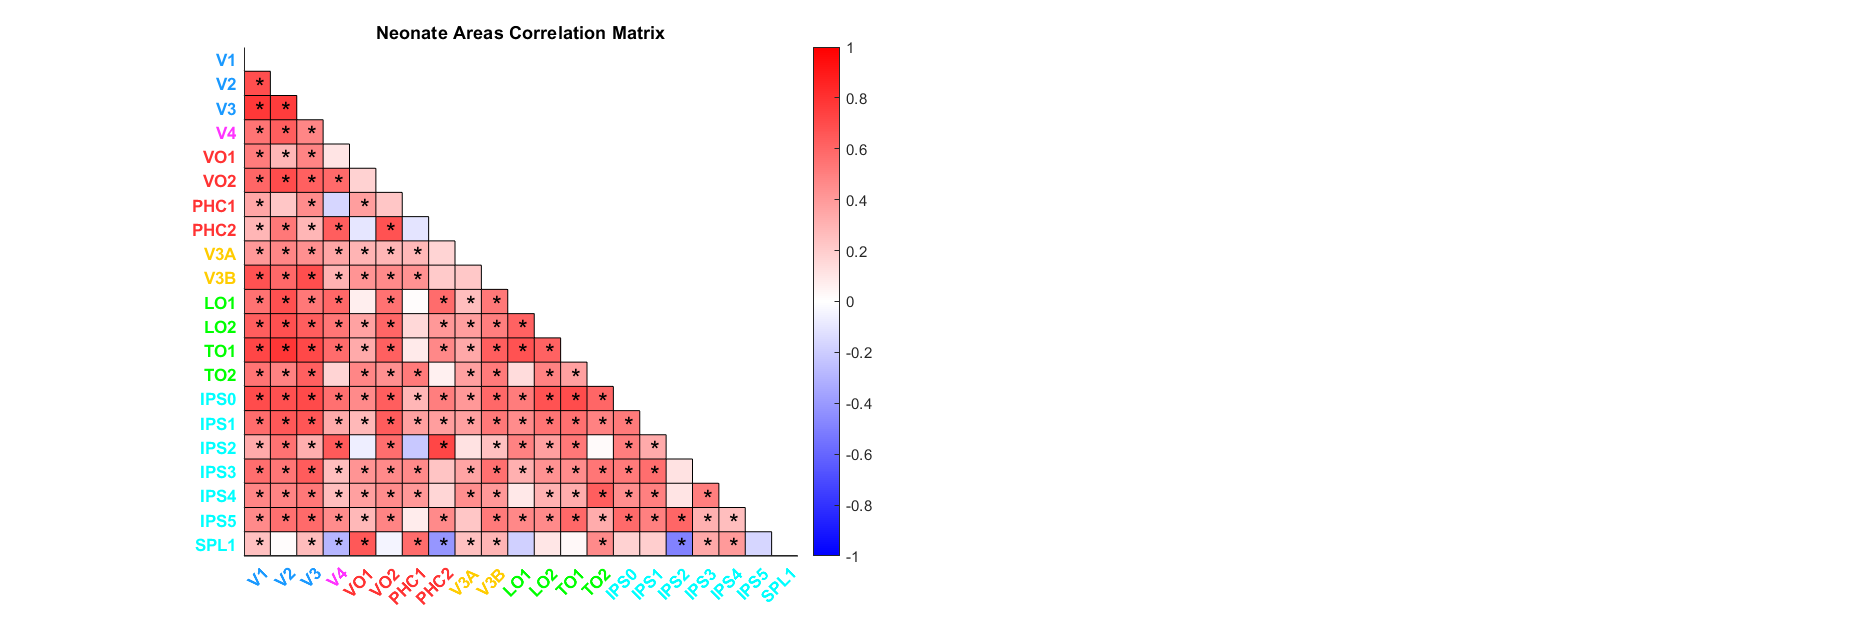

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
subplot(1,2,1)
Z = ones(size(all_area_corr_neo,1), size(all_area_corr_neo,2), 3);  %black background
image(Z);
hold on;
lower_tri = tril(all_area_corr_neo);
lower_tri(1:length(lower_tri)+1:end) = 0;
p_tri = tril(all_area_pval_neo);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;
alphadata = double(lower_tri ~= 0);

h1 = imagesc(all_area_corr_neo);
h1.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_neo,1)
    for j = 1:size(all_area_corr_neo,2)
        if p_tri(j,i)<0.05
            text(i-0.1,j+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_neo)
        plot([j+0.5 j+0.5],[j+0.5 length(all_area_corr_neo)+0.5],'k')
        end
    end
    plot([i+0.5 0],[i+0.5 i+0.5],'k')
end
Xticklabels_new = cell(size(alllabels_human_merge));
Yticklabels_new = cell(size(alllabels_human_merge));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], EVCcolor);
end
for i = 4
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], V4color);
end
for i = 5:8
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], ventralcolor);
end
for i = 9:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], dorsalcolor);
end
for i = 11:14
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], lateralcolor);
end
for i = 15:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human_merge{i},'}'], parietalcolor);
end

ax = gca;
set(ax, 'XTick',1:length(alllabels_human_merge),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_human_merge),'YTickLabel',Yticklabels_new)
% set(ax,'xaxisLocation','top')
box off;
ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];

colormap(redblue);c = colorbar;caxis([-1 1]);
title('Neonate Areas Correlation Matrix')